Text: R_e = 137.04, r_e = 1

clear
clc

eve_color = 'r';
adam_color = 'b';

r_e = 1;
R_e = 20; %137.04; % 10;
% alpha = 1/137.0366;
[theta,phi] = meshgrid(linspace(0,2*pi,50));
r = r_e;
R = R_e;
x = (R + r*cos(theta)).*cos(phi);
y = (R + r*cos(theta)).*sin(phi);
z = r*sin(theta);
% figure(1)
% surf(x,y,z)
% shading interp
% colormap gray
% axis equal

Text: set Q, get R, Get L, get Lz, get v, get p, get E, get B, Abraham, Loretz, Dirac.

n_eve = 25; % 
n_adam = 1/2; % 

plot_eve = 1;
plot_adam = 0;

eve_loops = 1;
if mod(n_eve, 1) ~= 0
   eve_loops = 2*1/mod(n_eve, 1);
end

adam_loops = 1;
if mod(n_adam, 1) ~= 0
   adam_loops = 2*1/mod(n_adam, 1);
end
c = 1;
v = 0.0*c;

c_alpha = 0.5;

phase0_eve = 0;
phase0_adam = pi;

eve_path = getKnotLikePaths(v,eve_loops,R,r,n_eve,phase0_eve);
adam_path = getKnotLikePaths(v,adam_loops,R,r,n_adam,phase0_adam);

%%%
[diff_path, diff_length] = getDiffPath(eve_path);
sum_diff_length = sum(diff_length);
paths_ratio = sum_diff_length/(2*pi*R);
disp(['Paths ratio = ',num2str(paths_ratio)])

Paths ratio = 1.59


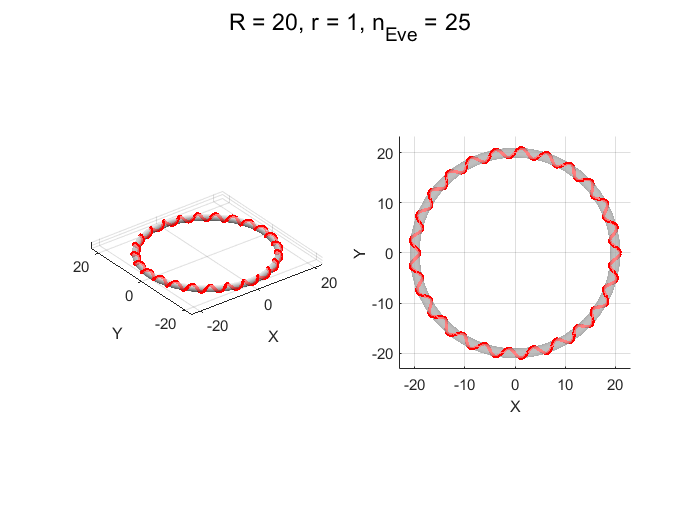

%%%

fig1 = figure;
if plot_adam
suptitle(['R = ',num2str(R),', r = ', num2str(r),...
    ', n_{Eve} = ',num2str(n_eve), ', n_{Adam} = ',num2str(n_adam)])
else
suptitle(['R = ',num2str(R),', r = ', num2str(r),...
    ', n_{Eve} = ',num2str(n_eve)])
    
end

%% 3D view
subplot(1,2,1)
surf(x,y,z,'FaceAlpha',c_alpha)
shading interp
colormap gray
axis equal
hold on
if plot_eve
    plot3(eve_path(:,1), eve_path(:,2), eve_path(:,3), '-',...
        'Color', eve_color,'LineWidth',2)
end
if plot_adam
    plot3(adam_path(:,1), adam_path(:,2), adam_path(:,3), '-',...
        'Color', adam_color,'LineWidth',2)
end
hold off

xlabel('X')
ylabel('Y')
zlabel('Z')

axis equal
axis(1.1*[-(R+r) R+r -(R+r) R+r -r r])
grid on
%% Top view
subplot(1,2,2)
surf(x,y,z,'FaceAlpha',0.5)
shading interp
colormap gray
axis equal
hold on
if plot_eve
    plot3(eve_path(:,1), eve_path(:,2), eve_path(:,3), '-',...
        'Color', eve_color,'LineWidth',2)
end
if plot_adam
    plot3(adam_path(:,1), adam_path(:,2), adam_path(:,3), '-',...
        'Color', adam_color,'LineWidth',2)
end
hold off

xlabel('X')
ylabel('Y')
zlabel('Z')

axis equal
axis(1.1*[-(R+r) R+r -(R+r) R+r -r r])
view(2)


save_image = 0;
if save_image
    saveas(fig1,['quarks_path_n',num2str(n_eve),'.png'])
end



% 45